clear all
clc
img = imread(['..\DB1/db1_11.jpg']);
%imshow(generateFaceMask(colorCorrection(im2double(img))).*im2double(img
% fm =  generateFaceMask(colorCorrection(im2double(img)));
% mm = mouthMask(colorCorrection(im2double(img)),fm)
% imshow(mm.*im2double(img))



%6 11
eyeCoords = findEyeCoordinates(img);
eyeL = eyeCoords(1, :)

eyeL =   176.6214    8.1359


eyeR = eyeCoords(2, :)

eyeR =   262.5559    8.3921


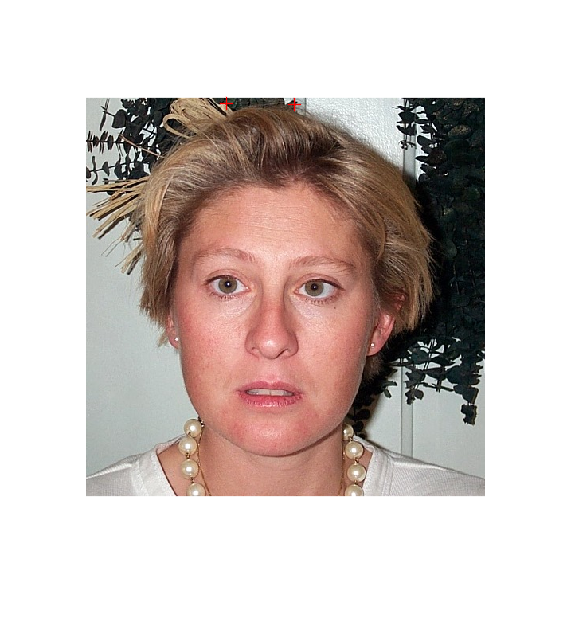

imgD = im2double(img);
normalface = normalizeFace(eyeL, eyeR, imgD);
imshow(img)

hold on
plot(eyeCoords(1,1),eyeCoords(1,2), 'r+', 'MarkerSize', 10, 'LineWidth', 1);
plot(eyeCoords(2,1),eyeCoords(2,2), 'r+', 'MarkerSize', 10, 'LineWidth', 1);
hold off


% temp = 'C:\Users\jakob\Documents\GitHub\DB0\db0_4.jpg'
% r = 5
% 
% img = imread(temp);
% 
% %img = imrotate(img,r,'bicubic');
% 
% %eyeCoords = findEyeCoordinates(img);
% %cc = colorCorrection(img);
% 
% % img = im2double(img)
% % img = colorCorrection(img);
% % fm = generateFaceMask(img);
% % imshow(img)
% %imshowpair(img, cc, 'montage')
% 
%result=createEigenDB('..\DB1/', img)
totCorrect = 0;
temp = '';
avg = 0;
for i = 1:16
    if i < 10
        temp = strcat('..\DB1/db1_0',int2str(i));
        temp = strcat(temp,'.jpg');
    else
        temp = strcat('..\DB1/db1_',int2str(i));
        temp = strcat(temp,'.jpg');
    end
    i
    
    rotation = randi([-5,5])
    toneValue = randi([70,130])/100
    
    img = imread(temp);
    
    %img = imrotate(img,rotation,'bicubic');
    %img = img*toneValue;
    
    [result,dist]=createEigenDB('..\DB1/', img);
    result
    dist
    if i == result
        totCorrect = totCorrect +1;
        'Pass'
    else
        'Fail'
    end
    '========='
end

i = 1

rotation = 0

toneValue = 1.1700

eyeSize =      2     2


result = 1

dist = 9.9367e-13

ans = 'Pass'

ans = '========='

i = 2

rotation = 5

toneValue = 0.7700

eyeSize =      2     2


result = 2

dist = 4.1808e-12

ans = 'Pass'

ans = '========='

i = 3

rotation = 1

toneValue = 0.9800

eyeSize =      2     2


result = 3

dist = 5.6508e-12

ans = 'Pass'

ans = '========='

i = 4

rotation = -5

toneValue = 0.9000

eyeSize =      2     2


result = 4

dist = 9.8820e-13

ans = 'Pass'

ans = '========='

i = 5

rotation = -4

toneValue = 1.1800

eyeSize =      2     2


result = 5

dist = 5.7322e-12

ans = 'Pass'

ans = '========='

i = 6

rotation = -2

toneValue = 1.0200

eyeSize =      2     2


result = 6

dist = 3.9098e-12

ans = 'Pass'

ans = '========='

i = 7

rotation = -4

toneValue = 1.0600

eyeSize =      2     2


result = 7

dist = 2.5008e-12

ans = 'Pass'

ans = '========='

i = 8

rotation = -3

toneValue = 1.0900

eyeSize =      2     2


result = 8

dist = 2.7859e-12

ans = 'Pass'

ans = '========='

i = 9

rotation = 2

toneValue = 1.1500

eyeSize =      2     2


result = 9

dist = 1.4957e-12

ans = 'Pass'

ans = '========='

i = 10

rotation = -1

toneValue = 0.7500

eyeSize =      2     2


result = 10

dist = 7.4360e-12

ans = 'Pass'

ans = '========='

i = 11

rotation = -3

toneValue = 1.2500

eyeSize =      2     2


result = 11

dist = 1.8335e-11

ans = 'Pass'

ans = '========='

i = 12

rotation = -4

toneValue = 1.2000

eyeSize =      2     2


result = 12

dist = 5.1638e-12

ans = 'Pass'

ans = '========='

i = 13

rotation = 0

toneValue = 1.3000

eyeSize =      2     2


result = 13

dist = 1.1418e-12

ans = 'Pass'

ans = '========='

i = 14

rotation = -5

toneValue = 0.9700

eyeSize =      2     2


result = 14

dist = 1.9663e-12

ans = 'Pass'

ans = '========='

i = 15

rotation = -4

toneValue = 1.2800

eyeSize =      2     2


result = 15

dist = 1.7202e-12

ans = 'Pass'

ans = '========='

i = 16

rotation = -5

toneValue = 1.1700

eyeSize =      2     2


result = 16

dist = 3.6658e-12

ans = 'Pass'

ans = '========='


% for i = 1:4
%     temp = strcat('..\DB0/db0_',int2str(i));
%     temp = strcat(temp,'.jpg');
% 
%     i
%     img = imread(temp);
%     [result,dist] = createEigenDB('..\DB1/', img);
%     dist
%     if 0 == result
%         totCorrect = totCorrect +1;
%         'Pass'
%     else
%         'Fail'
%     end
%     '========='
% end
% 'Stats'
totCorrect

totCorrect = 16

procentCorrect = 100*totCorrect/20

procentCorrect = 80

avg/20

ans = 0

rotation = 1

toneValue = 0.0400

scale = 0.9300

translation = 30

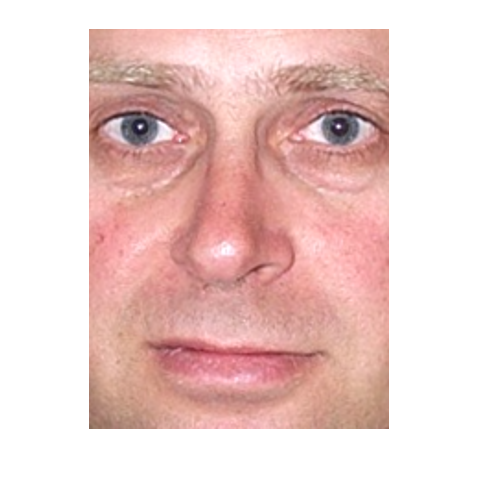

minerror = 0.0786

ans = 'Pass'

ans = '========='

rotation = -1

toneValue = -0.1200

scale = 1.0800

translation = 17

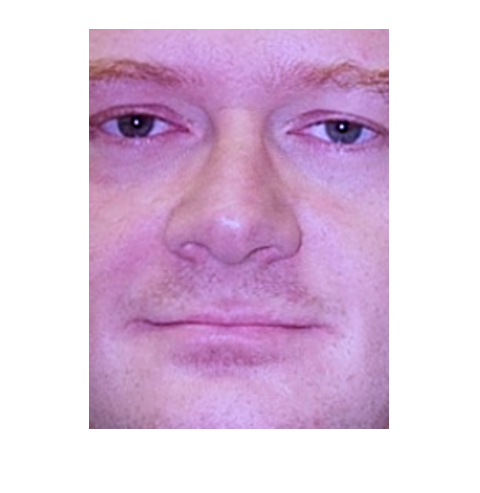

minerror = 0.0720

ans = 'Pass'

ans = '========='

rotation = 4

toneValue = -0.0900

scale = 1.0400

translation = 8

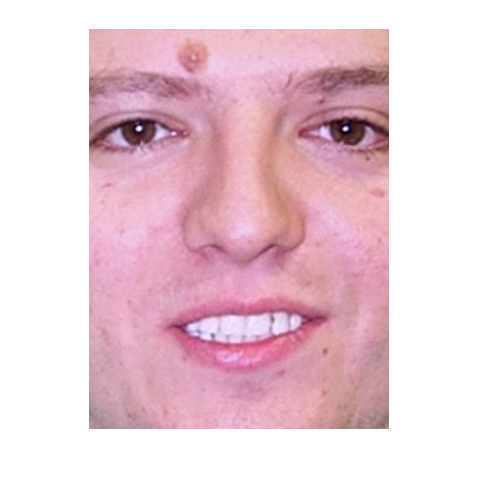

minerror = 0.0985

ans = 'Pass'

ans = '========='

rotation = -4

toneValue = -0.0400

scale = 0.9500

translation = 15

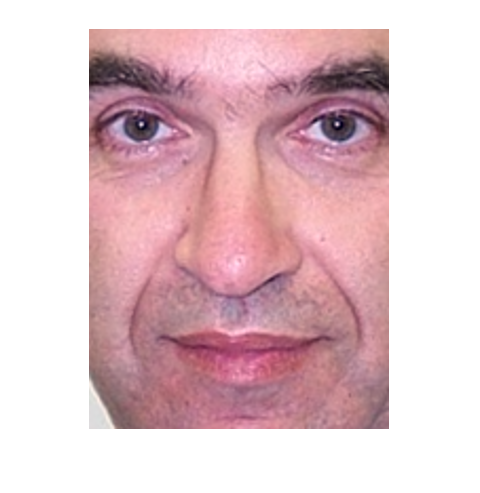

minerror = 0.0333

ans = 'Pass'

ans = '========='

rotation = -2

toneValue = 0.1600

scale = 1.0700

translation = -18

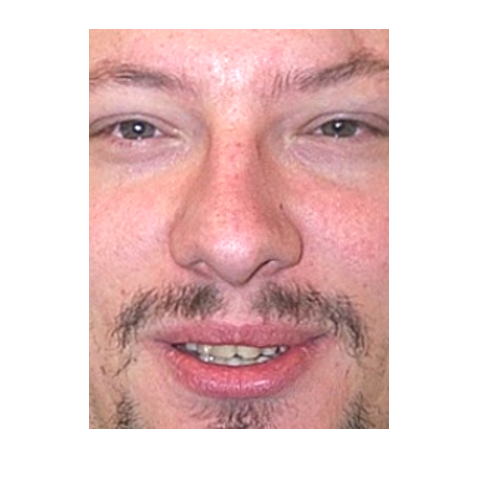

minerror = 0.1075

ans = 'Pass'

ans = '========='

rotation = 0

toneValue = 0.0800

scale = 1.0700

translation = 4

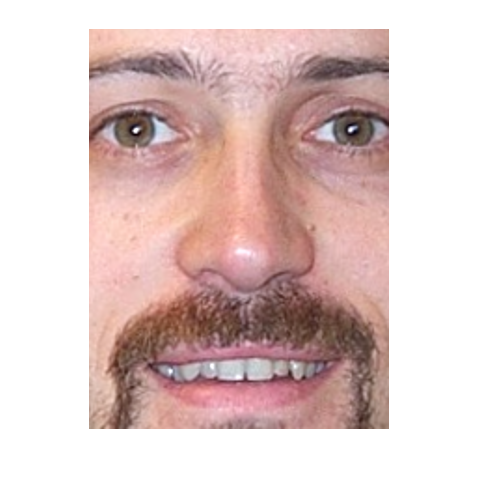

minerror = 0.0710

ans = 'Pass'

ans = '========='

rotation = 1

toneValue = -0.0700

scale = 0.9900

translation = 11

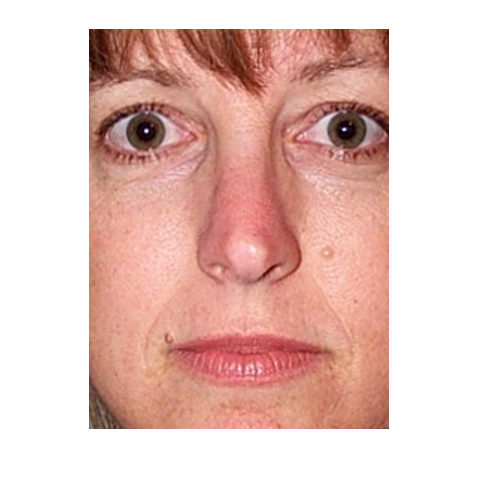

minerror = 0.1432

ans = 'Pass'

ans = '========='

rotation = 4

toneValue = 0.0900

scale = 0.9000

translation = 10

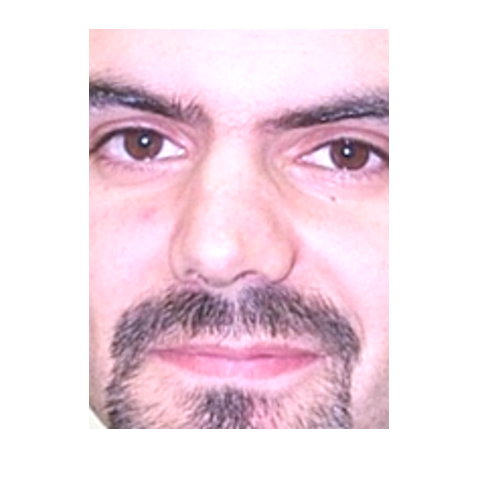

minerror = 0.6041

ans = 'Fail'

imageI = 8

ans = '========='

rotation = -1

toneValue = -0.0300

scale = 0.9200

translation = 30

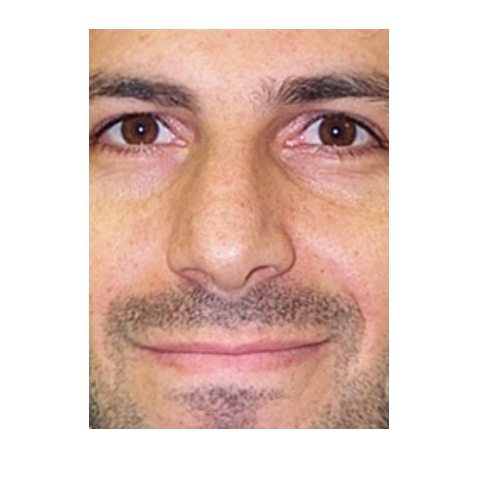

minerror = 0.0297

ans = 'Pass'

ans = '========='

rotation = -2

toneValue = -0.1000

scale = 0.9700

translation = -16

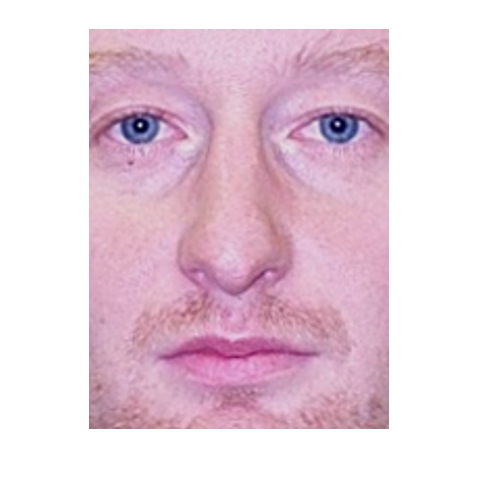

minerror = 0.1082

ans = 'Pass'

ans = '========='

rotation = 1

toneValue = 0.0300

scale = 0.9800

translation = -10

ans = 'Fail'

imageI = 11

ans = 'FailEyeCoords'

ans = '========='

rotation = 0

toneValue = 0.0600

scale = 1.0900

translation = 30

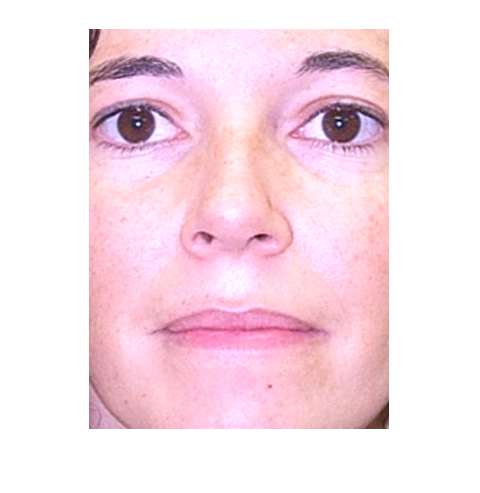

minerror = 0.1240

ans = 'Pass'

ans = '========='

rotation = -1

toneValue = 0.1400

scale = 0.9200

translation = -46

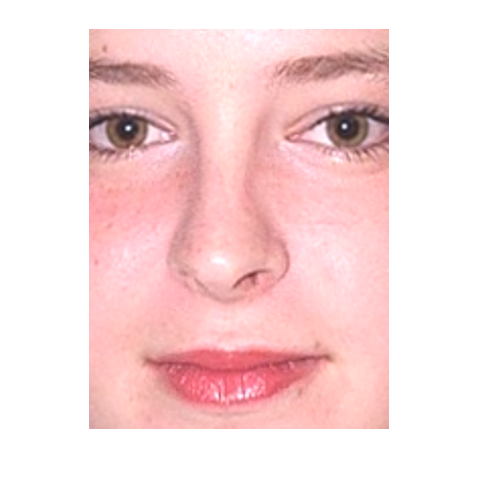

minerror = 0.2101

ans = 'Pass'

ans = '========='

rotation = -5

toneValue = -0.1400

scale = 0.9600

translation = -25

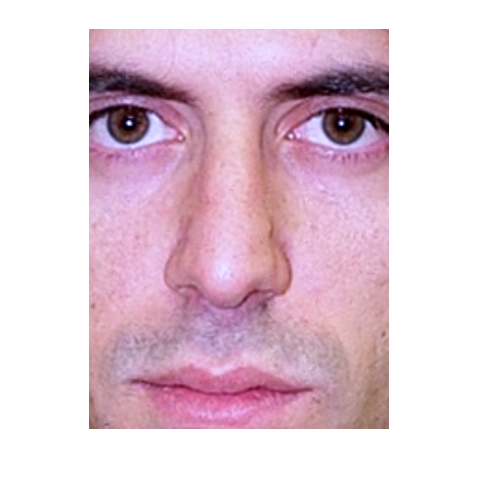

minerror = 0.2883

ans = 'Pass'

ans = '========='

rotation = -5

toneValue = 0.0200

scale = 0.9200

translation = -39

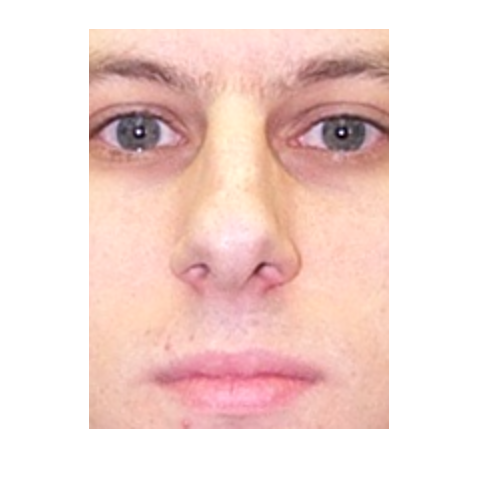

minerror = 0.0983

ans = 'Pass'

ans = '========='

rotation = 1

toneValue = 0.1500

scale = 1.1000

translation = 3

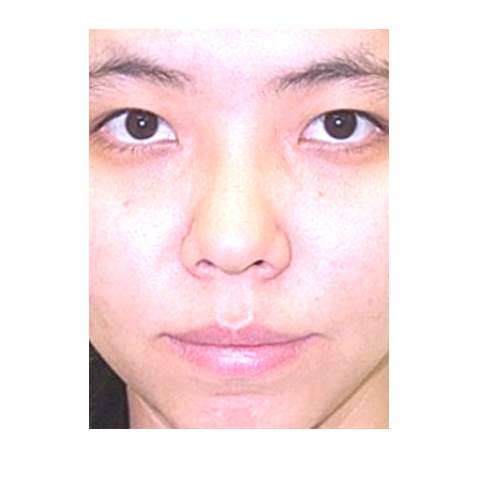

minerror = 0.1864

ans = 'Pass'

ans = '========='

Settings
height = NORMALIZED_FACE_HEIGHT;
width = NORMALIZED_FACE_WIDTH;

totCorrect = 0;
temp = '';
avg = 0;


for imageI = 1:16
    %Get image path
    if imageI < 10
        temp = strcat('..\DB1/db1_0',int2str(imageI));
        temp = strcat(temp,'.jpg');
    else
        temp = strcat('..\DB1/db1_',int2str(imageI));
        temp = strcat(temp,'.jpg');
    end
    
    
    %Get image
    img = im2double(imread(temp));

    
    %Random rotation and tone shift in all rgb channels
    rotation = randi([-5,5])
    %rotation = 5;
    toneValue = randi([-20,20])/100
    scale = randi([90,110])/100
    imSize = size(img);
    translation = randi([-floor(imSize(1)/10),floor(imSize(2)/10)])
    %toneValue = 0.20;
    %Apply rotation and shift
    img = imrotate(img,rotation,'bicubic','crop');
    img = imresize(img, scale);
    %img = imtranslate(img, [translation, translation]);
    img = img+toneValue;
    img(img(:,:,:) < 0) = 0;
    img(img(:,:,:) > 1) = 1;


    

    figure
    
    img = colorCorrection(img);
    %imshow(img);
    
    eyecords = findEyeCoordinates(img);
    output = 0;
    if eyecords ~= 0
        eyeR = eyecords(2,:);
        eyeL = eyecords(1,:);
        normalface = normalizeFace(eyeL, eyeR, img);
        imshow(normalface)
        image = rgb2gray(normalface);
        x1 = reshape(image, height * width, 1);
        w1 = fisherFaces' * x1;
    
        for i = 1:length(weights)
            errors(i) = norm(w1 - weights(:,i));%) - norm(weights(:,i)));
        end
        errors = errors ./ max(errors);
        [minerror, index]  = min(errors);
        
        threshold = 0.35;
        if(minerror < threshold)
            output = index;
        else
            output = 0;
        end
        minerror
    end
    
    if imageI == output
        totCorrect = totCorrect +1;
        'Pass'
    else
        'Fail'

        imageI
        if eyecords == 0
            'FailEyeCoords'

        end
        if eyecords ~= 0
            %imshow(normalface)
        end
        
    end
    '========='
end



for imageI = 1:4
    
    %Read image
    figure
    temp = strcat('..\DB0/db0_',int2str(imageI));
    temp = strcat(temp,'.jpg');

    img = im2double(imread(temp));
    
    img = colorCorrection(img);
    eyecords = findEyeCoordinates(img);
    output = 0;
    if eyecords ~= 0
        eyeR = eyecords(2,:);
        eyeL = eyecords(1,:);
        normalface = normalizeFace(eyeL, eyeR, img);
        %imshow(normalface)
        image = rgb2gray(normalface);
        x1 = reshape(image, height * width, 1);
        w1 = fisherFaces' * x1;
    
        for i = 1:length(weights)
            errors(i) = norm(w1 - weights(:,i));%) - norm(weights(:,i)));
        end
        errors = errors ./ max(errors);
        [minerror, index]  = min(errors);
        
        threshold = 0.35;
        if(minerror < threshold)
            output = index;
        else
            output = 0;
        end
        minerror
    end
    
      
    if 0 == output || 99 == output
        totCorrect = totCorrect +1;
        'Pass'
    else
        'Fail'
        
    end
    '========='
end

minerror = 0.5287

ans = 'Pass'

ans = '========='

minerror = 0.5582

ans = 'Pass'

ans = '========='

minerror = 0.6364

ans = 'Pass'

ans = '========='

ans = 'Pass'

ans = '========='

'=========''Stats''========='

ans = '========='Stats'========='

totCorrect

totCorrect = 18